# Fit for AP1903 and BLAST data together:

## Full System*:


$$log(\hbox{ydata}) - log\left(\frac{N_0}{N_{confluent}}\right) =  (\psi_g + \psi_d)\cdot\frac{(\eta_AA + 1)^4 + \left(\frac{P_R}{\delta}\right)^4}{(\eta_B B_{ext} + 1)(\eta_AA+ 1)^4+ \left( \frac{P_R}{\delta} \right)^4 } - \psi_d-\psi_C \cdot \frac{\eta_{I} I \cdot  \left(\frac{P_C}{\delta}\right)^2}{\eta_{I}I \cdot \left(\frac{P_C}{\delta}\right)^2+(\eta_AA +1)^2} $$


## Blast =0:


$$log(\hbox{ydata}) - log\left(\frac{N_0}{N_{confluent}}\right) = \psi_g-\psi_C \frac{I^*\left(\frac{P_C}{\delta}\right)^2}{I^*\left(\frac{P_C}{\delta}\right)^2+(\eta_AA +1)^2}$$


## AP1903 =0: 


$$log(\hbox{ydata}) - log\left(\frac{N_0}{N_{confluent}}\right) =  (\psi_g + \psi_d)\cdot\frac{(\eta_AA + 1)^4 + \left(\frac{P_R}{\delta}\right)^4}{(\eta_B B_{ext} + 1)(\eta_AA+ 1)^4+ \left( \frac{P_R}{\delta} \right)^4 } - \psi_d$$


*Note that ydata is the ratio of cell number to confluent cell number 

Input the observation axuin levels:

clear all; close all

xdata = ...
 [ 0 .2 .5 1 2 5 10 20 50 100];

## Input the  responses Line S1-3 for BLAST and AP1903: 

%%NoAP1903
ydata1 = ...
    [0.994351247	0.9916548	0.989389418	0.996206878	0.994587755	0.983118519	0.893697128	0.400989342	0.006447241	0.00148715];
%%NoBlast
 ydata2 = ...
    [0.020884656	0.038708919	0.053608692	0.0795322	0.106651625	0.426742328	0.801811791	0.927911111	0.978334618	0.916049206];
%%Both 
ydata_both = [ydata1;ydata2];

## Fit the data to the model. 

## AP1903 =0: 


$$log(\hbox{ydata}) - log\left(\frac{N_0}{N_{confluent}}\right) =  (\psi_g + \psi_d)\cdot\frac{(\eta_AA + 1)^4 + \left(\frac{P_R}{\delta}\right)^4}{(\eta_B B_{ext} + 1)(\eta_AA+ 1)^4+ \left( \frac{P_R}{\delta} \right)^4 } - \psi_d$$


## Blast =0:


$$log(\hbox{ydata}) - log\left(\frac{N_0}{N_{confluent}}\right) = \psi_g-\psi_C \frac{I^*\left(\frac{P_C}{\delta}\right)^2}{I^*\left(\frac{P_C}{\delta}\right)^2+(\eta_AA +1)^2}$$


  x(1) = $\psi_g =\delta$ (let vary for curiosity) , x(2) = $\eta_A$, x(3) = $\psi_C$, x(4) = $I^* P_C^2$, x(5) = $\psi_d$,  x(6) = $B^* =\eta_B B_{\textrm{ext}}$, x(7) = $P_R$ 


rate_both = @(x,xdata)([(((x(1) + x(5)).*((x(2).*xdata +1).^4 + (x(7)./x(1)).^4)./((x(6) + 1).*(x(2).*xdata +1).^4 + (x(7)./x(1)).^4)) - x(5));(x(1)- x(3).*((x(4)./x(1)).^2./((x(4)./x(1)).^2 + (x(2).*xdata + 1).^2)))].*50);

fun_both = @(x,xdata)(exp(rate_both(x,xdata) - log(4)));


 options = optimoptions('lsqcurvefit','MaxFunctionEvaluations',25000, 'MaxIterations',4000);
x0_both = [0.03 2 .01 .1 1 1 2];
% 
 [x_both,renorm_both,residual_both] = lsqcurvefit(fun_both,x0_both,xdata,ydata_both,[0 0 0 0 0 0 0],[inf  inf inf inf inf inf inf],options);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


MSE_both = mean((residual_both).^2,2); % mean percentage error 
MPE_both = mean((residual_both)./ydata1,2).*100; % mean percentage error 

## Plot the data and the fitted curve.

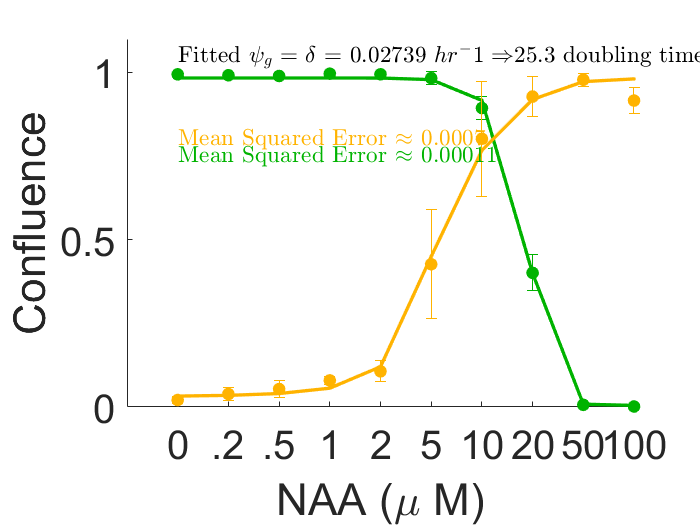

%%standard_dev
err1 = [0.002809344	0.005162316	0.004957646	0.001467934	0.002520465	0.019980023	0.033964324	0.054158992	0.002579971	0.000759584];
err2 = [0.010813322	0.018252794	0.026223576	0.012246634	0.031479622	0.16338727	0.171613373	0.059727441	0.01959887	0.03884396];

times =xdata;

y_both = fun_both(x_both,times);

figure(1)

e1 = errorbar([1:length(xdata)],ydata1,err1,'o','Color',[0,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[0,.7,0],'MarkerFaceColor',[0,.7,0]);
hold on 
p1 = plot([1:length(xdata)],y_both(1,:),'.-','Color',[0,.7,0],'MarkerFaceColor',[0,.7,0],'LineWidth',2);

e2 = errorbar([1:length(xdata)],ydata2,err2,'o','Color',[1,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,.7,0],'MarkerFaceColor',[1,.7,0]);
hold on 
p2 = plot([1:length(xdata)],y_both(2,:),'.-','Color',[1,.7,0],'MarkerFaceColor',[1,.7,0],'LineWidth',2);

xticklabels({'0','.2','.5','1','2','5','10', '20', '50', '100'})
xlabel('NAA (\mu M)')
ylabel({'Confluence'})
ax1 = gca;
ax1.FontSize = 24;
ylim([0,1.1])
% ax.FontWeight = 'bold';
box off

%legend([e1, e2, p1, p2],'Experimental Data No AP1903','Experimental Data No BLAST','Model Fit No AP1903','Model Fit No BLAST','FontSize',14,'Location','Best')
text(1,.75,['Mean Squared Error $ \approx$ ',num2str(round(MSE_both(1),5))],'Interpreter','Latex','Color',[0,.7,0],'FontSize',14)
text(1,.8,['Mean Squared Error $ \approx$ ',num2str(round(MSE_both(2),4))],'Interpreter','Latex','Color',[1,.7,0],'FontSize',14)
text(1,1.05,['Fitted $\psi_g = \delta$ = ',num2str(round(x_both(1),5)),'$ \,\, hr^-1 \Rightarrow$',num2str(round(log(2)./x_both(1),2)),' doubling time'],'Interpreter','Latex','FontSize',14)

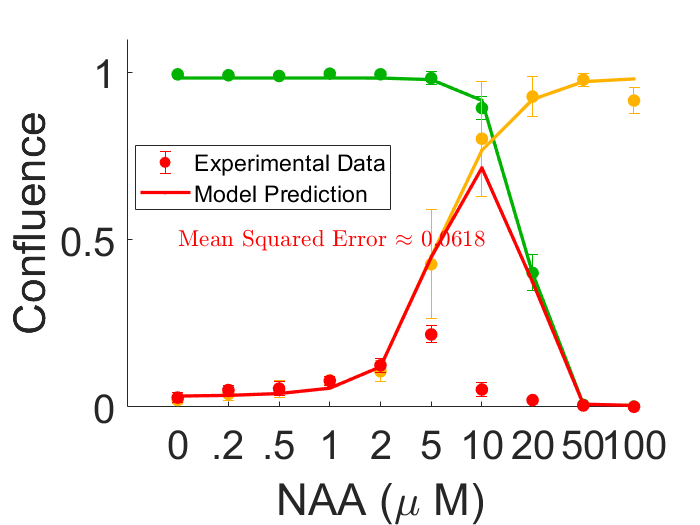

figure(2)

%biphasic data 
ydata3 = ...
[0.028152532	0.050824187	0.055106803	0.078311489	0.12464966	0.216782237	0.052270824	0.020610733	0.004709373	0.000569237];
%biphasic data error 
err3 = [0.014081056	0.012390267	0.020057457	0.012582435	0.020161014	0.025438707	0.021837773	0.007677594	0.004816866	0.00058251];
%biphasic function  
rate3 = @(x,xdata)((((x(1) + x(5)).*((x(2).*xdata +1).^4 + (x(7)./x(1)).^4)./((x(6) + 1).*(x(2).*xdata +1).^4 + (x(7)./x(1)).^4)) - x(5) - x(3).*((x(4)./x(1)).^2./((x(4)./x(1)).^2 + (x(2).*xdata + 1).^2))  ).*50);
fun3 = @(x,xdata)(exp(rate3(x,xdata) - log(4)));
%Mean squared prediction error
residual_pred = fun3(x_both,times)-ydata3;
MSE_pred = mean((residual_pred).^2,2); % mean percentage error 
MPE_pred = mean((residual_pred)./ydata1,2).*100; % mean percentage error 


e12 = errorbar([1:length(xdata)],ydata1,err1,'o','Color',[0,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[0,.7,0],'MarkerFaceColor',[0,.7,0]);
hold on 
p1 = plot([1:length(xdata)],y_both(1,:),'.-','Color',[0,.7,0],'MarkerFaceColor',[0,.7,0],'LineWidth',2);

e22 = errorbar([1:length(xdata)],ydata2,err2,'o','Color',[1,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,.7,0],'MarkerFaceColor',[1,.7,0]);
hold on 
p2 = plot([1:length(xdata)],y_both(2,:),'.-','Color',[1,.7,0],'MarkerFaceColor',[1,.7,0],'LineWidth',2);

e3 = errorbar([1:length(xdata)],ydata3,err3,'o','Color',[1,0,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,0,0],'MarkerFaceColor',[1,0,0]);
hold on 
p3 = plot([1:length(xdata)],fun3(x_both,times),'.-','Color',[1,0,0],'MarkerFaceColor',[1,0,0],'LineWidth',2);

xticklabels({'0','.2','.5','1','2','5','10', '20', '50', '100'})
xlabel('NAA (\mu M)')
ylabel({'Confluence'})
ax1 = gca;
ax1.FontSize = 24;
ylim([0,1.1])
% ax.FontWeight = 'bold';
box off

legend([e3, p3],'Experimental Data ','Model Prediction ','FontSize',14,'Location','Best')%
text(1,.5,['Mean Squared Error $ \approx$ ',num2str(round(MSE_pred,4))],'Interpreter','Latex','Color',[1,0,0],'FontSize',14)

# *Conclusions and Questions*

- Fitting both AP1903 and BLAST data together yields to good fits.

- However, these parameters still do not predict the biphasic data well. 

- What other mechanisms or model structures could be explain biphasic data?

# Fit for AP1903, BLAST, and Biphasic data together:

## Input the  responses Line S1-3 for BLAST and AP1903: 

%%All 
ydata_all = [ydata1;ydata2;ydata3];

## Fit the data to the model. 


rate_all = @(x,xdata)([(((x(1) + x(5)).*((x(2).*xdata +1).^4 + (x(7)./x(1)).^4)./((x(6) + 1).*(x(2).*xdata +1).^4 + (x(7)./x(1)).^4)) - x(5));...
    (x(1)- x(3).*((x(4)./x(1)).^2./((x(4)./x(1)).^2 + (x(2).*xdata + 1).^2)));...
    (((x(1) + x(5)).*((x(2).*xdata +1).^4 + (x(7)./x(1)).^4)./((x(6) + 1).*(x(2).*xdata +1).^4 + (x(7)./x(1)).^4)) - x(5) - x(3).*((x(4)./x(1)).^2./((x(4)./x(1)).^2 + (x(2).*xdata + 1).^2)))].*50);

fun_all = @(x,xdata)(exp(rate_all(x,xdata) - log(4)));


x0_all = [0.03 2 .01 .1 1 1 2];
% 
[x_all,renorm_both,residual_all] = lsqcurvefit(fun_all,x0_all,xdata,ydata_all,[0 0 0 0 0 0 0],[inf  inf inf inf inf inf inf],options);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


MSE_all = mean((residual_all).^2,2); % mean percentage error 
MPE_all = mean((residual_all)./ydata1,2).*100; % mean percentage error 

## Plot the data and the fitted curve.

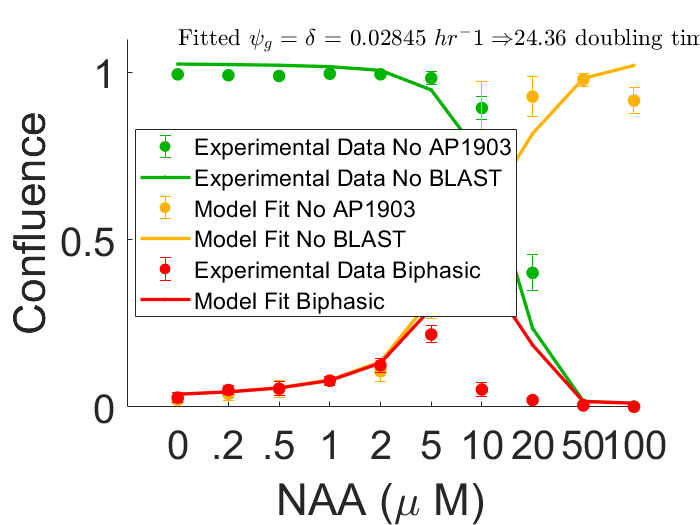

y_all = fun_all(x_all,times);
close all
figure(3)
e11 = errorbar([1:length(xdata)],ydata1,err1,'o','Color',[0,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[0,.7,0],'MarkerFaceColor',[0,.7,0]);
hold on 
p11 = plot([1:length(xdata)],y_all(1,:),'.-','Color',[0,.7,0],'MarkerFaceColor',[0,.7,0],'LineWidth',2);

e22 = errorbar([1:length(xdata)],ydata2,err2,'o','Color',[1,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,.7,0],'MarkerFaceColor',[1,.7,0]);
hold on 
p22 = plot([1:length(xdata)],y_all(2,:),'.-','Color',[1,.7,0],'MarkerFaceColor',[1,.7,0],'LineWidth',2);

e3 = errorbar([1:length(xdata)],ydata3,err3,'o','Color',[1,0,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,0,0],'MarkerFaceColor',[1,0,0]);
hold on 
p3 = plot([1:length(xdata)],y_all(3,:),'.-','Color',[1,0,0],'MarkerFaceColor',[1,0,0],'LineWidth',2);

xticklabels({'0','.2','.5','1','2','5','10', '20', '50', '100'})
xlabel('NAA (\mu M)')
ylabel({'Confluence'})
ax1 = gca;
ax1.FontSize = 24;
ylim([0,1.1])
% ax.FontWeight = 'bold';
box off
legend([e11, p11, e22, p22, e3, p3],'Experimental Data No AP1903','Experimental Data No BLAST','Model Fit No AP1903','Model Fit No BLAST','Experimental Data Biphasic','Model Fit Biphasic','FontSize',14,'Location','Best')
text(1,.55,['Mean Squared Error $ \approx$ ',num2str(round(MSE_all(1),5))],'Interpreter','Latex','Color',[0,.7,0],'FontSize',14)
text(1,.6,['Mean Squared Error $ \approx$ ',num2str(round(MSE_all(2),4))],'Interpreter','Latex','Color',[1,.7,0],'FontSize',14)
text(1,.5,['Mean Squared Error $ \approx$ ',num2str(round(MSE_all(3),4))],'Interpreter','Latex','Color',[1,0,0],'FontSize',14)

text(1,1.1,['Fitted $\psi_g = \delta$ = ',num2str(round(x_all(1),5)),'$ \,\, hr^-1 \Rightarrow$',num2str(round(log(2)./x_all(1),2)),' doubling time'],'Interpreter','Latex','FontSize',14)

# *Conclusions and Questions*

- Fitting  AP1903 and BLAST and biphasic data  leads to parameters predict the biphasic a little better. 

# Growth Rate Curves

## Net Growth (parameters from all together fit):

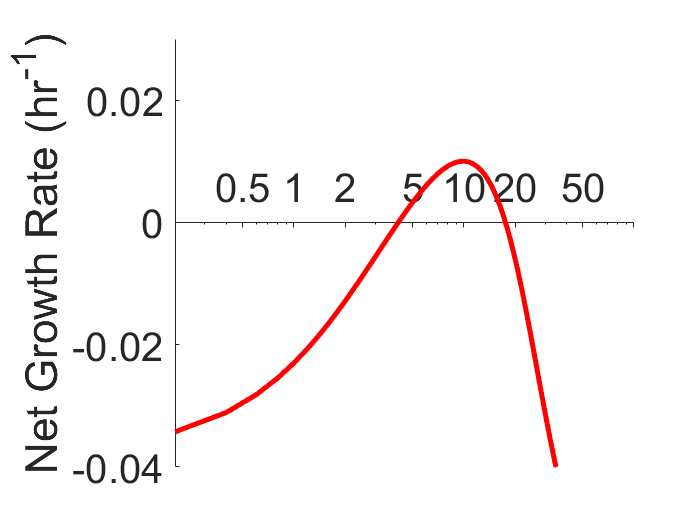


rate_allfit = @(x,xdata)(((x(1) + x(5)).*((x(2).*xdata +1).^4 + (x(7)./x(1)).^4)./((x(6) + 1).*(x(2).*xdata +1).^4 + (x(7)./x(1)).^4)) - x(5) - x(3).*((x(4)./x(1)).^2./((x(4)./x(1)).^2 + (x(2).*xdata + 1).^2))  );
times =linspace(xdata(1),200,1000);

figure(4)
dy1 = rate_allfit(x_all,times);

semilogx(times,dy1,'r-','LineWidth',3) 


 
xlh = xlabel('NAA (\muM)');
xlh.Position(2) = xlh.Position(2) - 0.001;
xlh.Position(1) = xlh.Position(1) + 5;

ylabel({'Net Growth Rate (hr^{-1})'})
ax1 = gca;
ax1.FontSize = 24;
ax1.XAxisLocation = 'origin';
ax1.YAxisLocation = 'origin';
% ax.FontWeight = 'bold';
box off

 xlim([.2,100])
 ylim([-.04,.03])
xticks([.2 .5 1 2 5 10 20 50 100])

## Death Rate  (parameters from all together fit):  

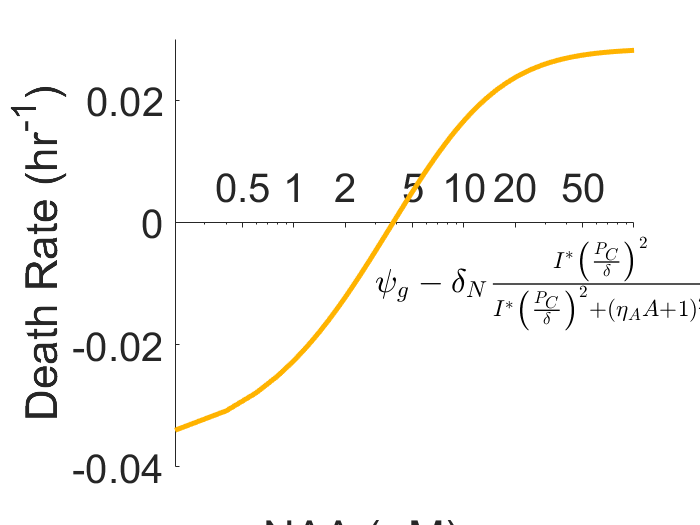

figure(5)
 
 ratedeath = @(x,xdata)((x(1)- x(3).*((x(4)./x(1)).^2./((x(4)./x(1)).^2 + (x(2).*xdata + 1).^2))));
 dy3 = ratedeath(x_all,times); 

 semilogx(times,dy3,'-','LineWidth',3,'Color',[1,.7,0]) 
 xlim([.2,100])
 

 
xlh2 = xlabel('NAA (\muM)');
xlh2.Position(2) = xlh2.Position(2) - 0.001;
xlh2.Position(1) = xlh2.Position(1) + 5;

ylabel({'Death Rate (hr^{-1})'})
ax = gca;
ax.FontSize = 24;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
% ax.FontWeight = 'bold';
box off

text(3,-.01,'$\psi_g-\delta_N \frac{I^*\left(\frac{P_C}{\delta}\right)^2}{I^*\left(\frac{P_C}{\delta}\right)^2+(\eta_AA +1)^2}$','Interpreter','Latex','FontSize',20)
 xticks([.2 .5 1 2 5 10 20 50 100])

 
 ylim([-.04,.03])

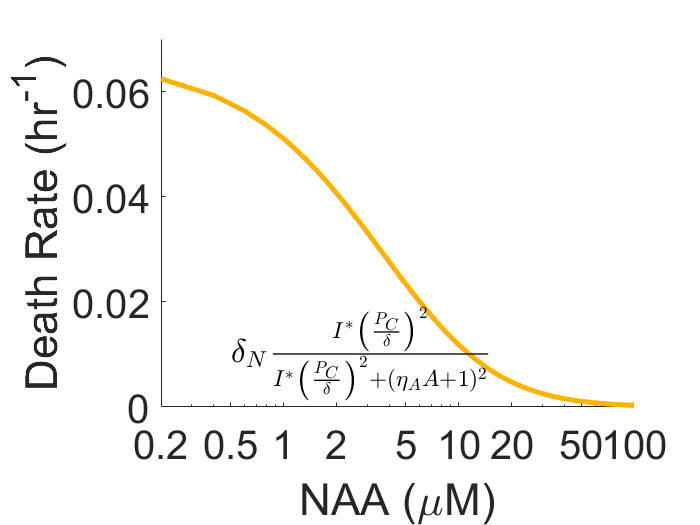


 
figure(6)
 ratedeath = @(x,xdata)(( x(3).*((x(4)./x(1)).^2./((x(4)./x(1)).^2 + (x(2).*xdata + 1).^2))));

 dy4 = ratedeath(x_all,times); 

 semilogx(times,dy4,'-','LineWidth',3,'Color',[1,.7,0]) 
 xlim([.2,100])
 
 
xlh3 = xlabel('NAA (\muM)');
% xlh3.Position(2) = xlh3.Position(2) - 0.02;
% xlh3.Position(1) = xlh3.Position(1) + 5;

ylabel({'Death Rate (hr^{-1})'})
ax = gca;
ax.FontSize = 24;
% ax.XAxisLocation = 'origin';
% ax.YAxisLocation = 'origin';
% ax.FontWeight = 'bold';
box off

text(.5,.01,'$\delta_N \frac{I^*\left(\frac{P_C}{\delta}\right)^2}{I^*\left(\frac{P_C}{\delta}\right)^2+(\eta_AA +1)^2}$','Interpreter','Latex','FontSize',20)
% title('AP1903')

 xticks([.2 .5 1 2 5 10 20 50 100])

 ylim([0,.07])

## Proliferation Rate  (parameters from all together fit):  

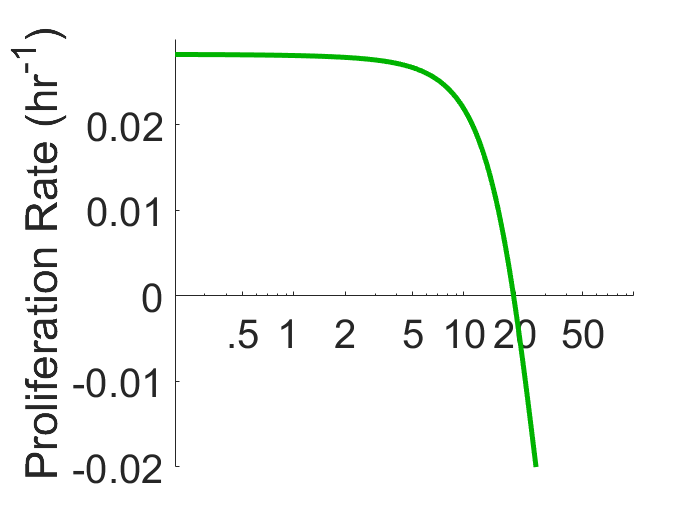

 
 figure(7)
 rateprolif = @(x,xdata)(((x(1) + x(5)).*((x(2).*xdata +1).^4 + (x(7)./x(1)).^4)./((x(6) + 1).*(x(2).*xdata +1).^4 + (x(7)./x(1)).^4)) - x(5));
 dy5 = rateprolif(x_all,times); 
 semilogx(times,dy5,'-','LineWidth',3,'Color',[0,.7,0]) 
 
% xlh4 = xlabel('NAA (\muM)');
%   xlh4.Position(2) = xlh4.Position(2) ;
%   xlh4.Position(1) = xlh4.Position(1)  ;

ylabel({'Proliferation Rate (hr^{-1})'})
ax = gca;
ax.FontSize = 24;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
% ax.FontWeight = 'bold';
box off

xticks([.2 .5 1 2 5 10 20 50 100])
 xticklabels({'.2' ,'.5' ,'1 ','2' ,'5' ,'10' ,'20' ,'50','100'})


 ylim([-.02,.03])
 
  xlim([.2,100])

# Time Trajectories 

## *Varied initial Conditions*

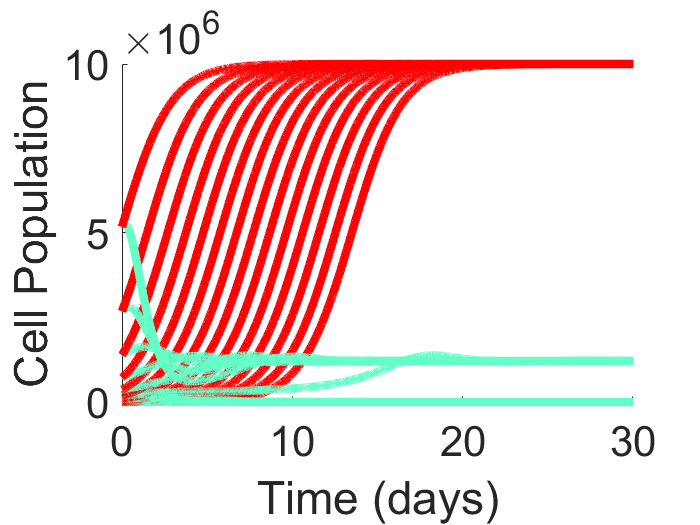

tspan = linspace(0,60*24,10000);

%Set known values
B_ext = .0473; %uM
I = 5; %uM

x_allp = x_all; 

x_allp(6)= x_all(6)./B_ext;

% Assume \kappa_C = .01
x_allp(4) = (1./.01)./x_allp(6);
lambdasq = x_all(4)./(x_allp(4).*x_allp(6).*I);

c1= logspace(3,7,15);
a1 = 10;%linspace(5,20,5);
[A1,N1] = meshgrid(a1,c1);
figure(12)

fs = [];
fcs = [];

for i = 1 : numel(A1)-1
    y0 = [A1(i),N1(i)];
    [t,f] = ode45(@(t,y,x) parodox_Elowitz1_fitnewnew(t,y,x_allp,B_ext,lambdasq,I),tspan,y0');
    [tc,fc] = ode45(@(t,y,x) parodox_Elowitz1_fitnewnew(t,y,x_allp,0,lambdasq,0 ),tspan,y0');
    
    fs = [fs, f(:, 2)];
    fcs = [fcs, fc(:, 2)];
    hold on
    plot(tspan./24,f(:,2),'Linewidth',5,'Color',[100,255,201]./255)
    plot(tspan./24,fc(:,2), 'Linewidth',5,'Color',[1,0,0])
end

save('Dynamcs', 'fs', 'fcs', 'tspan')
%  symlog('y')

xlabel('Time (days)')
ylabel('Cell Population')
xlim([0,30])
ylim([0,10*10^6])
ax1 = gca;
ax1.FontSize = 25;

# *Conclusions and Questions*

- Logscale does not yield a good graph. Uncomment (ax.YScale = 'log') and check for yourself.  

## *Paradoxical Feedback Response to Mutation*

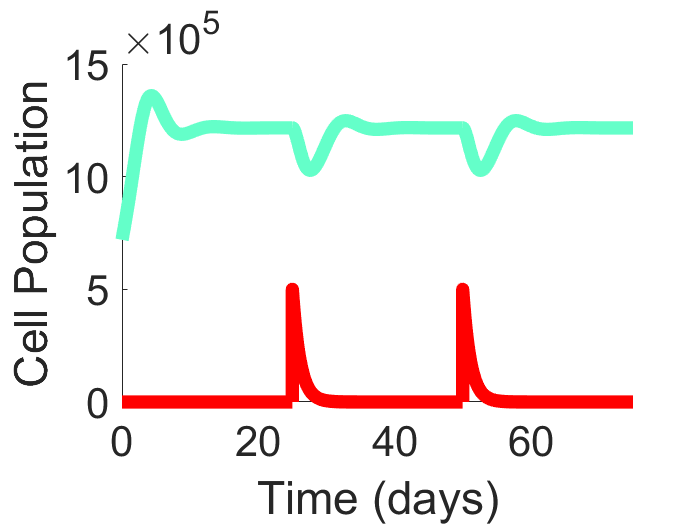

T1 = 25;
tspan1 = linspace(0,T1*24,10000);
y01 = [A1(numel(A1)-4),N1(numel(A1)-4),0];
[t1,f1] = ode45(@(t,y) parodox_Elowitz2_fitnewnew(t,y,x_allp,B_ext,lambdasq,I),tspan1,y01');

figure(13)
plot(t1./24,(f1(:,2)),'LineWidth',8,'Color',[100,255,201]./255)
hold on
plot(t1./24,(f1(:,3)),'LineWidth',8,'Color',[1,0,0])

%1st mutation
T2 = 50;
tspan2 = linspace(T1*24,T2*24,10000);
auxin_e2 = f1(end,1);
N_e2 = f1(end,2);
N_e1 = .5e6;

y02 = [auxin_e2,N_e2,N_e1];
[t2,f2] = ode45(@(t,y) parodox_Elowitz2_fitnewnew(t,y,x_allp,B_ext,lambdasq,I),tspan2,y02');
plot(t2./24,(f2(:,2)),'LineWidth',8,'Color',[100,255,201]./255)
hold on
plot([t1(end);t2]./24,([f1(end,3);f2(:,3)]),'LineWidth',8,'Color',[1,0,0])

%2nd mutation
T3 = 75;
tspan3 = linspace(T2*24,T3*24,10000);

auxin_e3 = f2(end,1);
N_e3 = f2(end,2);

y03 = [auxin_e3,N_e3,N_e1];
[t3,f3] = ode45(@(t,y) parodox_Elowitz2_fitnewnew(t,y,x_allp,B_ext,lambdasq,I),tspan3,y03');
h1 = plot(t3./24,(f3(:,2)),'LineWidth',8,'Color',[100,255,201]./255);
hold on
h2 = plot([t2(end);t3]./24,([f2(end,3);f3(:,3)]),'LineWidth',8,'Color',[1,0,0]);


xlabel('Time (days)')
ylabel('Cell Population')
xlim([0,75])
ax2 = gca;
ax2.FontSize = 25;
box off

% ax2.YScale = 'log'

## *Simple Feedback Response to Mutation*

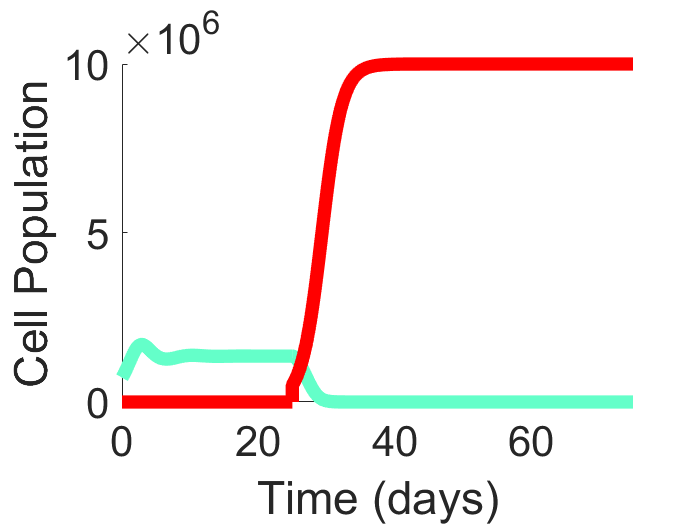

[t1,f1] = ode45(@(t,y) parodox_Elowitz3_fitnewnew(t,y,x_allp,B_ext,lambdasq,I),tspan1,y01');
figure(14)
plot(t1./24,(f1(:,2)),'LineWidth',8,'Color',[100,255,201]./255)
hold on
plot(t1./24,(f1(:,3)),'LineWidth',8,'Color',[1,0,0])

%1st mutation
T2 = 50;
tspan2 = linspace(T1*24,T3*24,10000);
auxin_e2 = f1(end,1);
N_e2 = f1(end,2);


y02 = [auxin_e2,N_e2,N_e1];
[t2,f2] = ode45(@(t,y) parodox_Elowitz3_fitnewnew(t,y,x_allp,B_ext,lambdasq,I),tspan2,y02');
plot(t2./24,(f2(:,2)),'LineWidth',8,'Color',[100,255,201]./255)
hold on
plot([t1(end);t2]./24,([f1(end,3);f2(:,3)]),'LineWidth',8,'Color',[1,0,0])



xlabel('Time (days)')
ylabel('Cell Population')
xlim([0,75])
ax3 = gca;
ax3.FontSize = 25;
box off

% ax3.YScale = 'log'
